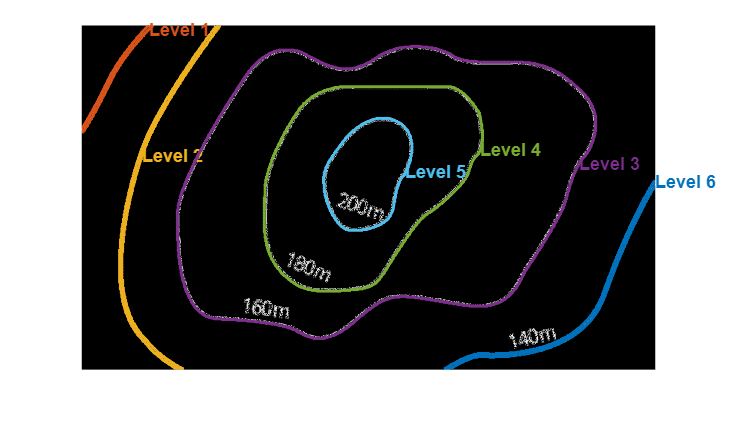

% 원본 등고선 이미지 불러오기
I = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\past.png');

% 모폴로지 연산으로 작은 잡음 제거
BW = bwareaopen(I, 800); % 1000픽셀 미만의 작은 객체 제거

% 등고선 추출
contours = bwboundaries(BW, 'noholes');

% 색상 맵 생성
colors = lines(length(contours));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(I);
hold on;
label_counter = 1;

for k = 1:length(contours)
    boundary = contours{k};

    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 2);
    
    % 등고선 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 12, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;

% 등고선 좌표 데이터를 CSV 파일로 저장
csv_filename = 'contour_data_test.csv';
fileID = fopen(csv_filename, 'w');
fprintf(fileID, 'Contour,X,Y\n'); % CSV 헤더: Contour, X, Y

for k = 1:length(contours)
    boundary = contours{k};
    contour_num = k;
    for i = 1:size(boundary, 1)
        fprintf(fileID, '%d,%f,%f\n', contour_num, boundary(i, 2), boundary(i, 1)); % X, Y 순서대로 저장
    end
end

fclose(fileID);
disp(['Contours saved to ' csv_filename]);

Contours saved to contour_data_test.csv


야호

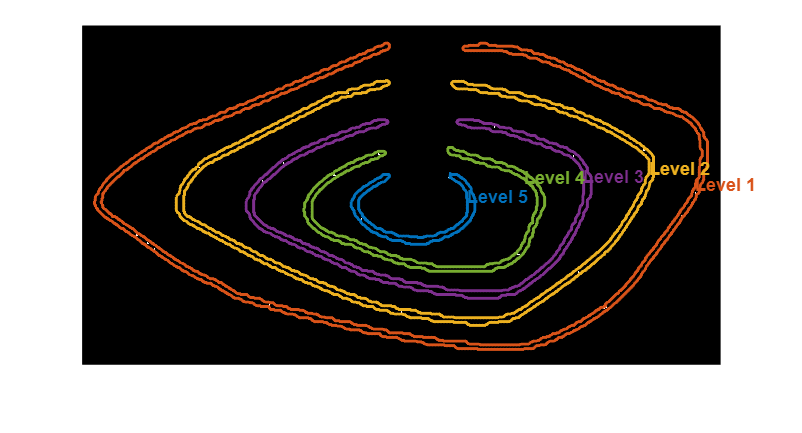

% 원본 등고선 이미지 불러오기
I_ = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\test2.png');

% 이미지를 그레이스케일로 변환
grayI = rgb2gray(I_);

% Canny 엣지 검출 적용
edges = edge(grayI, 'Canny');

% 팽창 연산을 통해 경계 강화
se = strel('disk', 1);  % 디스크 형태의 구조 요소 사용
BW_ = imdilate(edges, se);  % 경계 확대

% 작은 잡음 제거
BW_ = bwareaopen(BW_, 1500); % 100픽셀 미만의 작은 객체 제거

% 스켈레톤화
BW_ = bwmorph(BW_, 'skel', Inf);

% 등고선 추출
contours2 = bwboundaries(BW_, 'noholes');

% 색상 맵 생성
colors = lines(length(contours2));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(BW_);
hold on;
label_counter = 1;

for k = 1:length(contours2)
    boundary = contours2{k};

    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 2);
    
    % 등고선 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 12, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;


% 등고선 좌표 데이터를 CSV 파일로 저장
csv_filename = 'contour_data_test2.csv';
fileID = fopen(csv_filename, 'w');
fprintf(fileID, 'Contour,X,Y\n'); % CSV 헤더: Contour, X, Y

for k = 1:length(contours)
    boundary = contours{k};
    contour_num = k;
    for i = 1:size(boundary, 1)
        fprintf(fileID, '%d,%f,%f\n', contour_num, boundary(i, 2), boundary(i, 1)); % X, Y 순서대로 저장
    end
end

fclose(fileID);
disp(['Contours saved to ' csv_filename]);

Contours saved to contour_data_test2.csv


여기까지 2번

여기부터 3번

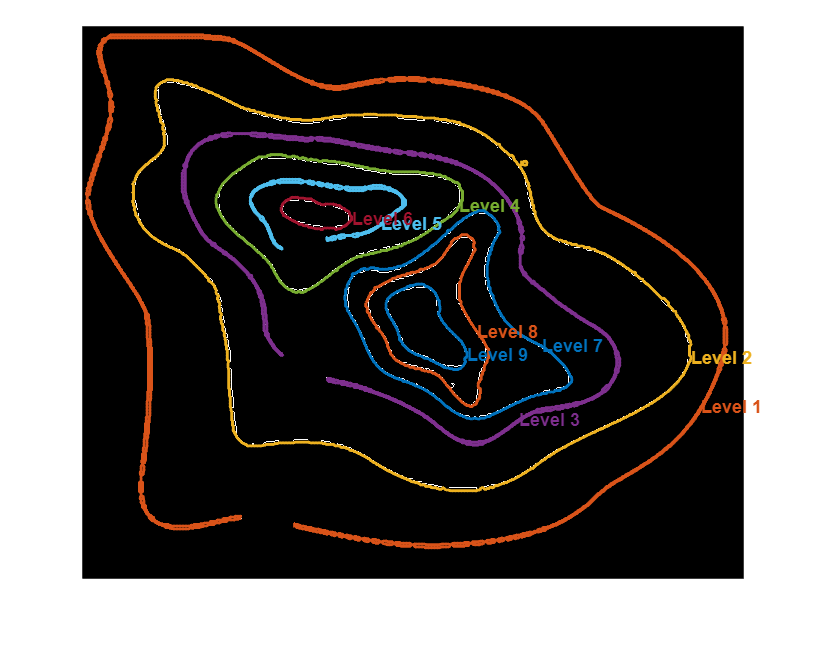

% 원본 등고선 이미지 불러오기
I_ = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\test3.png');

% 이미지를 그레이스케일로 변환
grayI = rgb2gray(I_);

% Canny 엣지 검출 적용
edges = edge(grayI, 'Canny');

% 팽창 연산을 통해 경계 강화
se = strel('disk', 1);  % 디스크 형태의 구조 요소 사용
BW_ = imdilate(edges, se);  % 경계 확대

% 작은 잡음 제거
BW_ = bwareaopen(BW_, 1000); % 100픽셀 미만의 작은 객체 제거

% 스켈레톤화
BW_ = bwmorph(BW_, 'skel', Inf);

% 등고선 추출
contours2 = bwboundaries(BW_, 'noholes');

% 색상 맵 생성
colors = lines(length(contours2));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(BW_);
hold on;
label_counter = 1;

for k = 1:length(contours2)
    boundary = contours2{k};

    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 2);
    
    % 등고선 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 12, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;


% 등고선 좌표 데이터를 CSV 파일로 저장
csv_filename = 'contour_data_test3.csv';
fileID = fopen(csv_filename, 'w');
fprintf(fileID, 'Contour,X,Y\n'); % CSV 헤더: Contour, X, Y

for k = 1:length(contours)
    boundary = contours{k};
    contour_num = k;
    for i = 1:size(boundary, 1)
        fprintf(fileID, '%d,%f,%f\n', contour_num, boundary(i, 2), boundary(i, 1)); % X, Y 순서대로 저장
    end
end

fclose(fileID);
disp(['Contours saved to ' csv_filename]);

Contours saved to contour_data_test3.csv


여기까지 3번

여기부터 4번

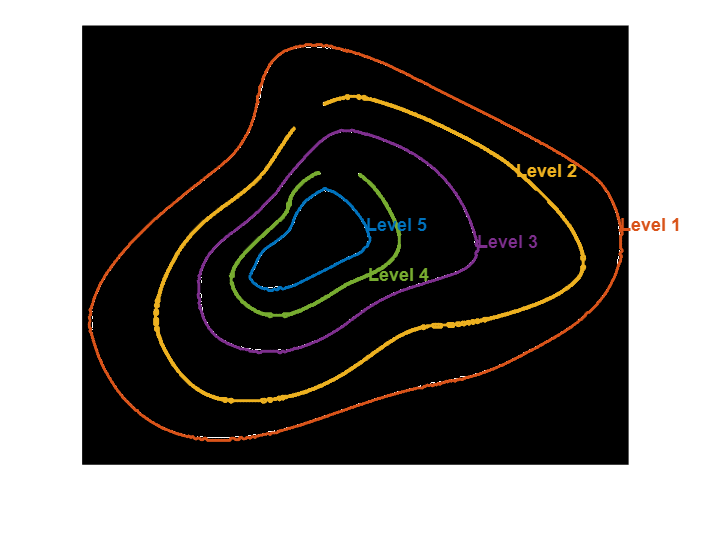

% 원본 등고선 이미지 불러오기
I_ = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\test4.png');

% 이미지를 그레이스케일로 변환
grayI = rgb2gray(I_);

% Canny 엣지 검출 적용
edges = edge(grayI, 'Canny');

% 팽창 연산을 통해 경계 강화
se = strel('disk', 1);  % 디스크 형태의 구조 요소 사용
BW_ = imdilate(edges, se);  % 경계 확대

% 작은 잡음 제거
BW_ = bwareaopen(BW_, 1000); % 100픽셀 미만의 작은 객체 제거

% 스켈레톤화
BW_ = bwmorph(BW_, 'skel', Inf);

% 등고선 추출
contours2 = bwboundaries(BW_, 'noholes');

% 색상 맵 생성
colors = lines(length(contours2));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(BW_);
hold on;
label_counter = 1;

for k = 1:length(contours2)
    boundary = contours2{k};

    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 2);
    
    % 등고선 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 12, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;

% 등고선 좌표 데이터를 CSV 파일로 저장
csv_filename = 'contour_data_test4.csv';
fileID = fopen(csv_filename, 'w');
fprintf(fileID, 'Contour,X,Y\n'); % CSV 헤더: Contour, X, Y

for k = 1:length(contours)
    boundary = contours{k};
    contour_num = k;
    for i = 1:size(boundary, 1)
        fprintf(fileID, '%d,%f,%f\n', contour_num, boundary(i, 2), boundary(i, 1)); % X, Y 순서대로 저장
    end
end

fclose(fileID);
disp(['Contours saved to ' csv_filename]);

Contours saved to contour_data_test4.csv


여기까지 4번

여기부터 5번

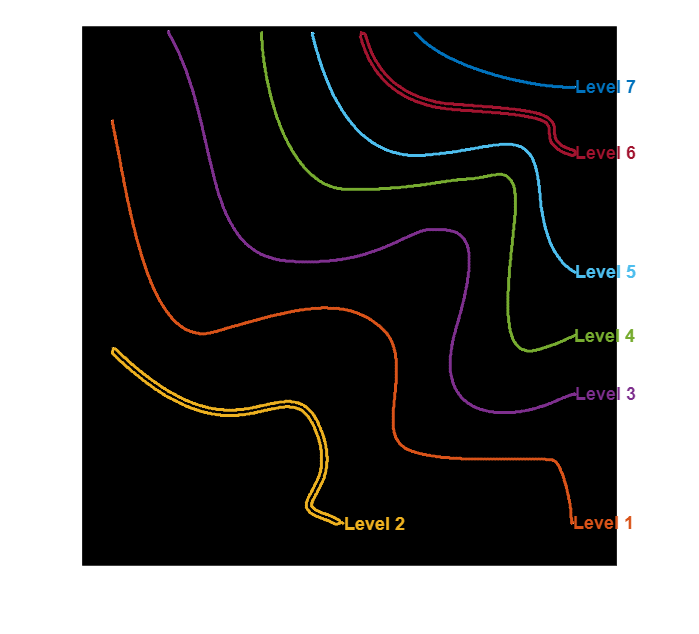

% 원본 등고선 이미지 불러오기
I_ = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\test5.png');

% 이미지를 그레이스케일로 변환
grayI = rgb2gray(I_);

% Canny 엣지 검출 적용
edges = edge(grayI, 'Canny');

% 팽창 연산을 통해 경계 강화
se = strel('disk', 2);  % 디스크 형태의 구조 요소 사용
BW_ = imdilate(edges, se);  % 경계 확대

% 작은 잡음 제거
BW_ = bwareaopen(BW_, 1500); % 100픽셀 미만의 작은 객체 제거

% 스켈레톤화
BW_ = bwmorph(BW_, 'skel', Inf);

% 등고선 추출
contours2 = bwboundaries(BW_, 'noholes');

% 색상 맵 생성
colors = lines(length(contours2));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(BW_);
hold on;
label_counter = 1;

for k = 1:length(contours2)
    boundary = contours2{k};

    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 2);
    
    % 등고선 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 12, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;

% 등고선 좌표 데이터를 CSV 파일로 저장
csv_filename = 'contour_data_test.csv';
fileID = fopen(csv_filename, 'w');
fprintf(fileID, 'Contour,X,Y\n'); % CSV 헤더: Contour, X, Y

for k = 1:length(contours)
    boundary = contours{k};
    contour_num = k;
    for i = 1:size(boundary, 1)
        fprintf(fileID, '%d,%f,%f\n', contour_num, boundary(i, 2), boundary(i, 1)); % X, Y 순서대로 저장
    end
end

fclose(fileID);
disp(['Contours saved to ' csv_filename]);

Contours saved to contour_data_test5.csv


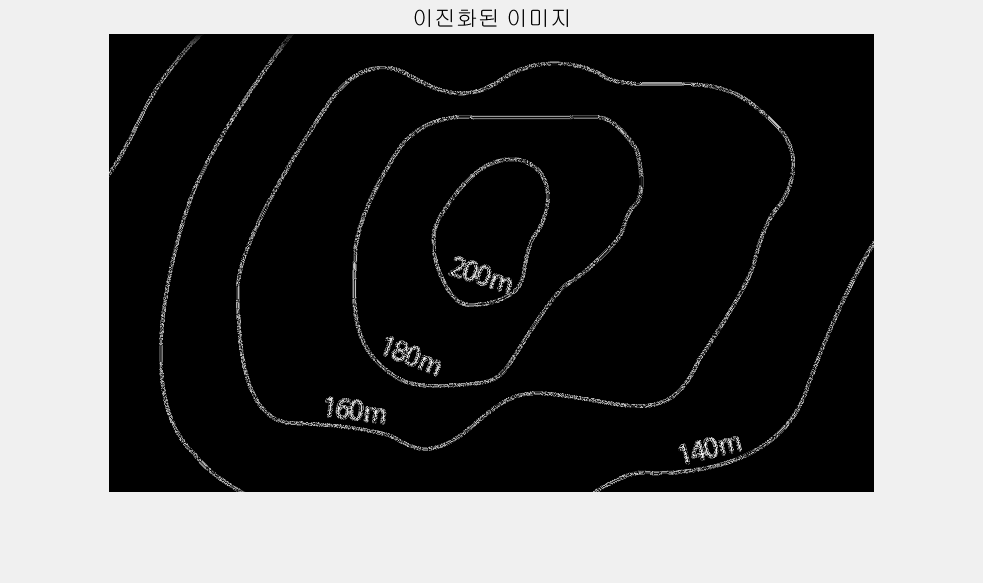

% 원본 등고선 이미지 불러오기
I = imread('D:\W00Y0NG\PRGM2\2024RNE_GEO\past.png');

% 그레이스케일로 변환 (컬러 이미지인 경우)
if size(I, 3) == 3
    I_gray = rgb2gray(I);
else
    I_gray = I;
end

% 그레이스케일 이미지 출력
figure;
imshow(I_gray);
title('그레이스케일 이미지');
set(gcf, 'Visible', 'on');

% 이진화 (바이너리 이미지 변환)
BW = imbinarize(I_gray);

% 이진화 반전 (흑백 반전)
BW = ~BW;

% 이진화된 이미지 출력
figure;
imshow(BW);
title('이진화된 이미지');

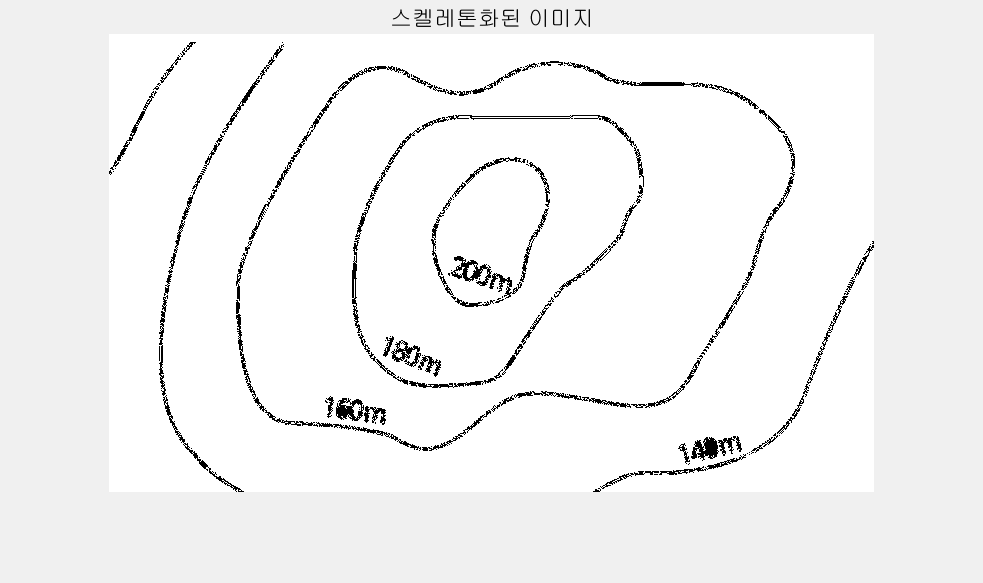

set(gcf, 'Visible', 'on');

% 모폴로지 연산으로 작은 잡음 제거
BW_ = bwareaopen(BW, 800); % 800픽셀 미만의 작은 객체 제거

% 작은 잡음 제거 후 이미지 출력
figure;
imshow(BW_);
title('작은 잡음 제거 후 이미지');
set(gcf, 'Visible', 'on');

% 스켈레톤화 수행
skeleton = bwmorph(BW_, 'skel', Inf);

% 스켈레톤화된 이미지 출력
figure;
imshow(skeleton);
title('스켈레톤화된 이미지');

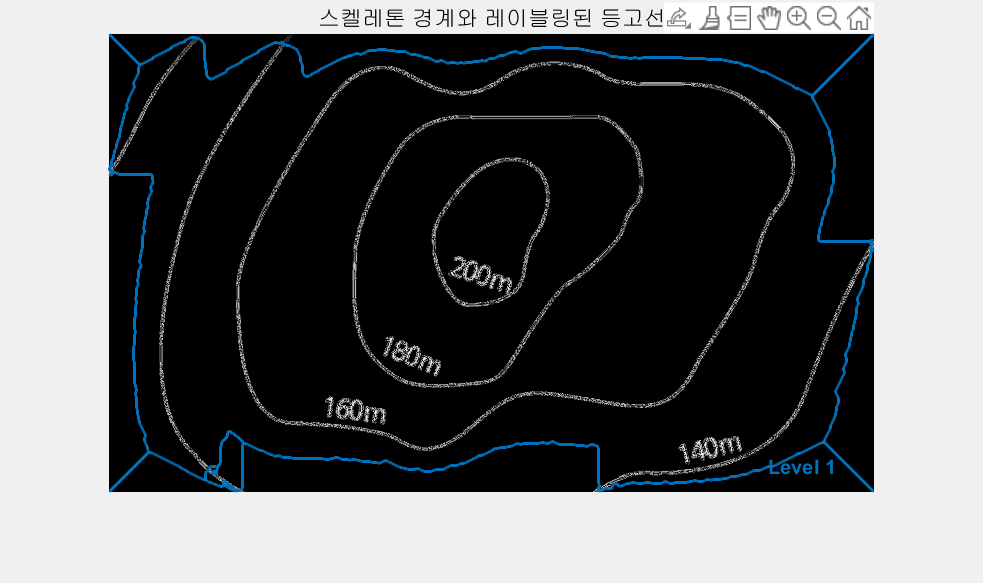

set(gcf, 'Visible', 'on');

% 스켈레톤 이미지에서 등고선 추출
contours = bwboundaries(skeleton, 'noholes');

% 색상 맵 생성
colors = lines(length(contours));

% 등고선 플롯 및 레이블링 (필터링 포함)
figure;
imshow(I_gray);
hold on;
label_counter = 1;

title('스켈레톤 경계와 레이블링된 등고선');
for k = 1:length(contours)
    boundary = contours{k};
    
    % 스켈레톤 경계 플롯
    plot(boundary(:,2), boundary(:,1), 'Color', colors(mod(k, size(colors, 1))+1,:), 'LineWidth', 1.5);
    
    % 스켈레톤 중앙에 레이블 추가
    mid_idx = round(size(boundary, 1) / 2);
    text(boundary(mid_idx, 2), boundary(mid_idx, 1), sprintf('Level %d', label_counter), ...
        'Color', colors(mod(k, size(colors, 1))+1,:), 'FontSize', 10, 'FontWeight', 'bold');
    label_counter = label_counter + 1;
end
hold off;
set(gcf, 'Visible', 'on');